# Second-Order Lab: Second-Order Linear DEs in MATLAB

In this lab, you will learn how to use `iode` to plot solutions of second-order ODEs. You will also learn to classify the behaviour of different types of solutions.

Moreover, you will write your own Second-Order ODE system solver, and compare its results to those of `iode`.

Opening the m-file lab5.m in the MATLAB editor, step through each part using cell mode to see the results.

There are seven (7) exercises in this lab that are to be handed in on the due date of the lab.

## Student Information

## Iode for Second-Order Linear DEs with constant coefficients

In the `iode` menu, select the `Second order linear ODEs` module. It opens with a default DE and a default forcing function `f(t) = cos(2t)`. The forcing function can be plotted along with the solution by choosing `Show forcing function` from the `Options` menu.

Use this module to easily plot solutions to these kind of equations.

There are three methods to input the initial conditions:

Method 1. Enter the values for `t0`, `x(t0)`, and `x'(t0)` into the `Initial conditions` boxes, and then click `Plot solution`.

Method 2. Enter the desired slope `x'(t0)` into the appropriate into the `Initial conditions` box, and then click on the graph at the point `(t0,x(t0))` where you want the solution to start.

Method 3. Press down the left mouse button at the desired point `(t0,x(t0))` and drag the mouse a short distance at the desired slope `x'(t0)`. When you release the mouse button, `iode` will plot the solution.

## Growth and Decay Concepts

We want to classify different kinds of behaviour of the solutions. We say that a solution:

`grows` if its magnitude tends to `infinity` for large values of `t`, that is, if either the solution tends to $+\infty$ or $-\infty$,

`decays` if its magnitude converges to `0` for large values of `t`,

`decays while oscillating` if it keeps changing sign for large values of `t` and the amplitude of the oscillation tends to zero,

`grows while oscillating` if it keeps changing sign for large values of `t` and the amplitude of the oscillation tends to infinity.

## Example

t = 0:0.1:10;

% Example 1
figure();
y1 = exp(t);
plot(t,y1)

% Annotate the figure
xlabel('t');
ylabel('f_1(t)');
title('The function e^t grows');
legend('f_1(t)=e^t');



% Example 2
figure();
y2 = -exp(-t);
plot(t,y2)

% Annotate the figure
xlabel('t');
ylabel('f_2(t)');
title('The function -e^{-t} decays');
legend('f_2(t)=-e^{-t}');



% Example 3
figure();
y3 = exp(-t);
plot(t,y3)

% Annotate the figure
xlabel('t');
ylabel('f_3(t)');
title('The function e^{-t} decays');
legend('f_3(t)=e^{-t}');



% Example 4
figure();
y4 = exp(-t).*cos(t);
plot(t,y4)

% Annotate the figure
xlabel('t');
ylabel('f_4(t)');
title('The function e^{-t}cos(t) decays while oscillating');
legend('f_4(t)=e^{-t}*cos(t)');



% Example 5
figure();
y5 = exp(t).*sin(2*t);
plot(t,y5)

% Annotate the figure
xlabel('t');
ylabel('f_5(t)');
title('The function e^{t}sin(2t) grows while oscillating');
legend('f_5(t)=e^{t}sin(2t)');



% Example 6
figure();
y6 = sin(3*t);
plot(t,y6)

% Annotate the figure
xlabel('t');
ylabel('f_6(t)');
title('The function sin(3t) neither decays nor grows, it just oscillates');
legend('f_6(t)=sin(3t)');



% |Remark.| A function which |grows while oscillating| doesn't |grow|,
% because it keeps changing sign, so it neither tends to $+\infty$ nor to
% $-\infty$.

## Exercise 1

Objective: Use `iode` to solve second-order linear DEs. And classify them.

Details: Consider the ODE:

(a) Use `iode` to plot six (6) numerical solutions of this equation with "random" initial data (use Method 3 above) and press-and-drag at various initial points, with some of the slopes being positive and some negative)

Use only initial points in the part of the window where `0<t<1` and `-1<x<1` and take all initial slopes between `-3` and `+3`.

Change the window to `[0,10]x[-3,3]`. Attach a cropped screenshot to your answers file.

(b) Based on the results of (a), state what percentage of solutions decay, grow, grow while oscillating, or decay while oscillating.

(c) Solve the DE and write the exact solution. Explain why this justifies your answer in (b).

b) All solutions decay while oscillating, except for the trivial solution y = 0

c) y(t) = exp(-t/2)*(C1*cos(2t)+C2*sin(2t))

This is verified by the analytical solution, which is a product of the exponential function with a negative exponent and sinusoidal terms. The function will oscillate about x=0 but due to the exp(-t/2) term and the negative exponent, the function will decay and approach zero as t grows for all initial values C1 and C2.

## Exercise 2

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

b) Almost all solutions grow, except the trivial solution y = 0 and when C1 = 0.

c) y(t) = C1*exp((-sqrt(3)+2)*t/2) + C2*exp((-sqrt(3)-2)*t/2)

The analytical solution has a positive exponential term exp((-sqrt(3)+2)*t/2). This means that all solutions will eventually grow to +/-infinity, depending on the sign of C1, given large t. Note the negative exponent term, (-sqrt(3)-2)t/2, will decay to 0 so it becomes insigificant with larges positive t's.

However, one case where the solutions decay instead of grow is when C1=0. In this case the positive exponential term is eliminated, leaving the negative exponential term, resulting in decaying solutions for all C2.

## Exercise 3

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

b) All solutions decay to 0 without oscillating, except for the trivial solution y = 0

c) y(t) = exp((-sqrt(3)+sqrt(2))t/2)) + C2*exp((-sqrt(3)-sqrt(2))t/2)

The analytical solution is a sum of exponentials, with both exponents negative. As t grows, both exponents approach 0, so the solution decays without oscillating (there is no sinusoidal term so no oscillations).

## Example

Consider the ODE:

The solution is

From this, it is easy to see that all solutions decay while oscillating.

Similarly, for the equation 

The solution is

which grows while oscillating.

## Exercise 4

Consider the fourth-order ODE:

(a) Find the general solution for this problem. You can use MATLAB to find the roots of the characteristic equation numerically with `roots`.

(b) Predict what percentage of solutions with random initial data will grow, decay, grow while oscillating, and decay while oscillating. Explain.

C = [1, 2, 6, 2, 5];
roots(C)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


The four roots to the equation are -1+2i, -1-2i, i, -i. Therefore the general solution is exp(-t)(Acos(2t)+Bsin(2t))+Ccos(t)+Dsin(t), where A,B,C, and D are arbitrary constants. Due to the sin and cos terms without the exponential (the C and D terms), the solution will not decay for large t. The first two terms which have exp(-t) as a factor will decay to zero, but the last two terms will conintue to oscillate. Therefore, for large t, the solutions will oscillate about y=0 without decay.

However, with the special case where C=D=0 and either A and B, or both, is nonzero, the solution will decay to zero since there is no longer terms without an exponential decay term, exp(-t), attached.

## Exercise 5

Objective: Classify equations given the roots of the characteristic equation.

Details: Your answer can consist of just a short sentence, as `grows` or  `decays while oscillating`.

Consider a second-order linear constant coefficient homogeneous DE with `r1` and `r2` as roots of the characteristic equation.

Summarize your conclusions about the behaviour of solutions for randomly chosen initial data when.

(a) `0 < r1 < r2`

(b) `r1 < 0 < r2`

(c) `r1 < r2 < 0`

(d) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha < 0`

(e) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha = 0`

(f) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha > 0`

`a) all solutions grow without oscillating`

`b) most solutions grow without osicllating, expect when the constant term attached to the r2 exponential is 0, in which case solutions decay without osicllating`

`c) all solutions decay without oscillating`

`d) all solutions decay while oscillating`

`e) all solutions oscillate without growth or decay (sinusoids)`

`f) all solutions grow while oscillating`

`The exception for all above classification is the trivial solution y=0, in which case the solution is constant with no growth, decay, or oscillations.`

## Numerical Methods for Second-Order ODEs

One way to create a numerical method for second-order ODEs is to approximate derivatives with finite differences in the same way of the Euler method.

This means that we approximate the first derivative by:

and

By writing these approximations into the, we obtain a method to get `y[n+1]` from the previous two steps `y[n]`  ODEand `y[n-1]`.

The method for approximating solutions is:

1. Start with `y[0]=y0`

2. Then we need to get `y[1]`, but we can't use the method, because we don't have two iterations `y[0]` and `y[-1]`(!!). So we use Euler to get

y1 is the slope given by the initial condition

3. Use the method described above to get `y[n]` for `n=2,3,...`

## Exercise 6

Objective: Write your own second-order ODE solver.

Details: Consider the second-order ODE

Write a second-order ODE solver using the method described above.

This m-file should be a function which accepts as variables (t0,tN,y0,y1,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0, y1 are the initial conditions of the ODE, and h is the stepsize. You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB lab 2). Name the function DE2_<UTORid>.m.

Note: you will need to use a loop to do this exercise. 

## Exercise 7

Objective: Compare your method with `iode`

Details: Use `iode` to plot the solution of the ODE  `y'' + exp(-t/5) y' + (1-exp(-t/5)) y = sin(2*t)` with the initial conditions  `y(0) = 1, y'(0) = 0`

Use the window to `[0,20]x[-2,2]` Without removing the figure window, plot your solution (in a different colour), which will be plotted in the same graph. 

Comment on any major differences, or the lack thereof.

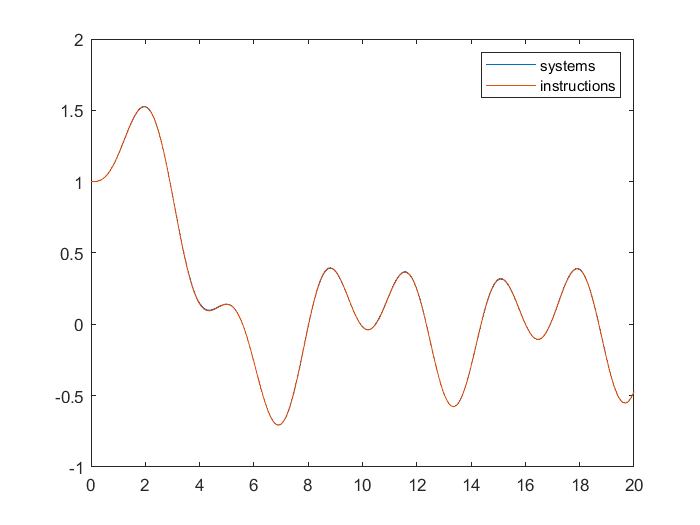

g = @(t) sin(2*t);
p = @(t) exp(-t/5);
q = @(t) 1-exp(-t/5);
y0 = 1;
y1 = 0;
t0 = 0;
tN = 20;
h = 0.01;
[t,y] = DE2_wuqingy6(t0,tN,y0,y1,h, p, q, g);
[t2,y2] = DE2b_wuqingy6_unofficial_method(t0,tN,y0,y1,h, p, q, g);

plot(t,y, t2, y2);
legend("proper", "unofficial");

There are no differences between my DE solver and iode's second order solver for the same time steps. However, if the step sizes are varied, some differences can be seen. The uploaded screenshot compares my DE solver solution (step sizze 0.01) with the iode solver (step size 0.05).

Note the solutions differ slightly whenever there is a large curvature derivative change in the graph, i.e., near the maximum and minimum values of the graph.

Note in the attached screeshot,  the blue graph is the approximation produced by DE2_wuqingy6, while the red graph is the approximation produced by iode.